% ДПТ
Mn = 0.12; % Нм
Jn = 0.21*1.25; % кг * м^2
Wm = 7.3% рад/с

Wm = 7.3000

Em = 2; % рад/с^2

a_max = 45; % град
M = 1.1;
b = 0.01; 


% % рассчитать требуемый от двигателя момент и номинальную мощность
% np = 0.66; % кпд редуктора
% Mm = Mn/np % значение минимальной мощности двигателя
% Pmin = 2*(Mm+Jn*Em) % минимальная мощность двигателя
% 

% Jdv = 8.59 * 10^-8; % момент инерции ротора двигателя ???
% Mnom = 0.03; % номинальный момент двигателя ???
% % Wnom = 795 * 2*pi/60 % номинальная скорость вращения двигателя ???
% 
% ipo = sqrt((Mnom+Jn*Em)/(1.2*Jdv*Em)) % оптимальное передаточное число
% % или
% ipo = Wnom/Wm
% 

% % Редуктор
% ip = 76; % передаточное число редуктора
% Mpmax = 3; % Максимальный крутящий момент
% np = 0.66; % КПД редутора
% %Jp = 1; % Момент инерции редуктора
% Jp = 0.3*Jdv
% 

% % Проверка 
% Mdin = (Jdv + Jp + Jn/ip^2)*ip*Em 
% Mc = Mn/(np*ip)
% 
% Mtr = Mdin + Mc
% 
% Ptr = Mtr*ip*Wm % должно быть Ptr < Pdv
% 
% ym = Mtr/Mnom % Должно быть в диапазоне от 3 до 5
% a = (ip*Wm)/Wnom % Должно быть в диапазоне от 0.8 до 0.9

Wnom = 4180;
Jdv = 1*0.0162/1000/100/100;
ip = 76;

magic1 = 10

magic1 = 10

magic2 = 0.00165

magic2 = 0.0017

check = 1

check = 1


k = 1/b %Коэффициент передачи системы

k = 100

kdv = (Wnom/15)/((Mn*2.1-Mn)/Wnom)

kdv = 8.8244e+06

Tm = ((Jdv*check)*magic1*Wnom)/((Mn*2.1-Mn))

Tm = 5.1300e-04

kred = 1/ip

kred = 0.0132

kyy = k/(kred*kdv)*magic2

kyy = 1.4211e-06

kn=kyy*kdv*kred

kn = 0.1650


s = tf('s');
wos = (kyy*kdv*kred)/(s^2*Tm + s)

wos =
 
       0.165
  ----------------
  0.000513 s^2 + s
 
Continuous-time transfer function.



% wcs = simplify(wos/(1 + wos))
wcs = (wos/(1 + wos))

wcs =
 
            8.464e-05 s^2 + 0.165 s
  --------------------------------------------
  2.632e-07 s^4 + 0.001026 s^3 + s^2 + 0.165 s
 
Continuous-time transfer function.



% bode(wcs)
% grid
% syms w
% Wjw = ( 0.008464*(1i*w)^2+16.5*(1i*w) ) / ( 2.632*10^(-7)*(1i*w)^4 + 0.001026*(1i*w)^3 + 1.008*(1i*w)^2 + 16.5*(1i*w) )
% A1=sqrt(real(Wjw)^2+imag(Wjw)^2);
% 
% fplot(A1,[0,100])
% grid on
% xlabel("Frequency")
% ylabel("Amplitude")
% title("АЧХ")
% legend("A(ω)")
wo = 1

wo = 1

wj = 1/(s^3 + 3*wo*s^2 + 3*wo*s + 1)

wj =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



% wj = 1/( s^2 + 9*s + 1)

% wreg = simplify(wj/(wos - wos*wj))
wreg = (wj/(wos - wos*wj))

wreg =
 
                                                                              
        2.632e-07 s^7 + 0.001027 s^6 + 1.003 s^5 + 3.003 s^4 + 3.001 s^3 + s^2
                                                                              
  ----------------------------------------------------------------------------------
                                                                                    
  8.464e-05 s^8 + 0.1655 s^7 + 0.9913 s^6 + 2.477 s^5 + 3.136 s^4 + 1.98 s^3        
                                                                                    
                                                                         + 0.495 s^2
                                                                                    
 
Continuous-time transfer function.



[n, d] = tfdata(wreg, 'v');
% n = 1
% d = 1

w = Em/Wm

w = 0.2740

A = Wm^2/Em

A = 26.6450

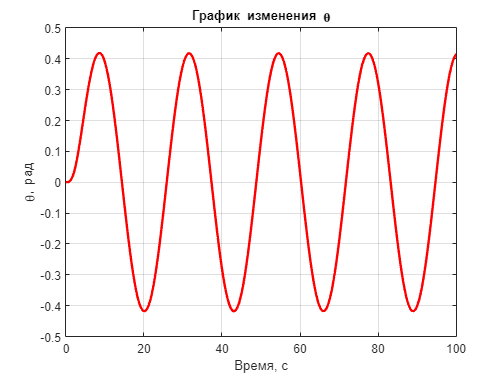


figure
plot(out.f2.time, out.f2.signals(1).values, 'r', 'LineWidth', 2)
title('График изменения \theta')
xlabel('Время, с')
ylabel('\theta, рад')
grid on

% ylim([0 46])